# Halpin-Tsai method

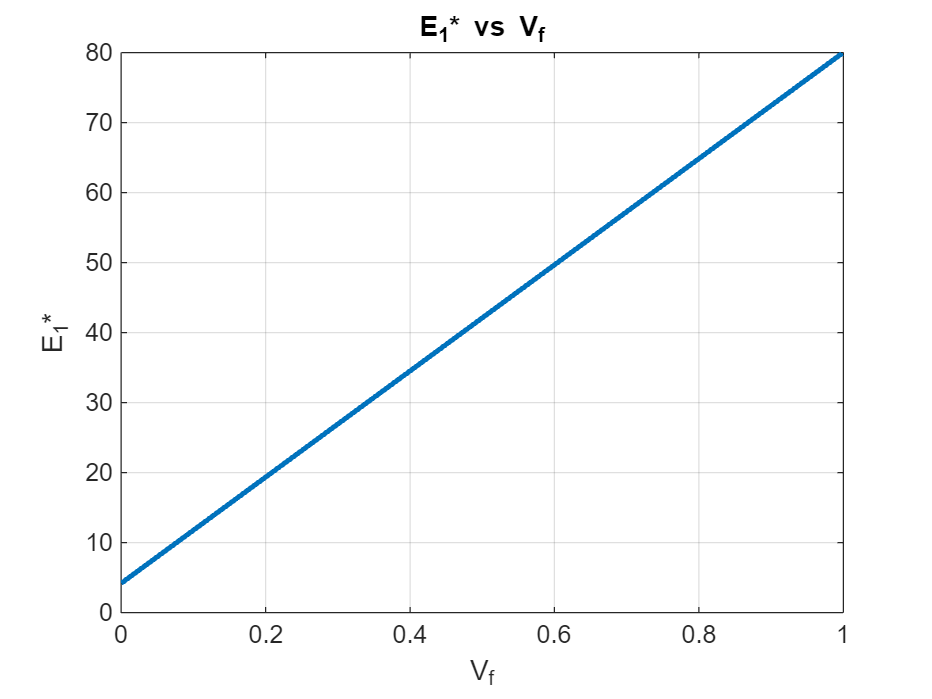

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

E_f = 80;
G_f = 33.33;
v_f = 0.2;

E_m = 4.2;
v_m = 0.34;
G_m = E_m/(2*(1+v_m));S

zeta = 2;

eta_1 = ((E_f/E_m) - 1) / ((E_f/E_m) + zeta);
E2_c = E_m * ((1 + zeta * eta_1 * Vf) / (1 - eta_1 * Vf));

eta_2 = ((G_f/G_m) - 1) / ((G_f/G_m) + zeta);
G12_c = G_m * ((1 + zeta * eta_2 * Vf) / (1 - eta_2 * Vf));

eta_3 = ((v_f/v_m) - 1) / ((v_f/v_m) + zeta);
v23_c = v_m * ((1 + zeta * eta_3 * Vf) / (1 - eta_3 * Vf));

%E1
E1_c = Vf * E_f + (1 - Vf) * E_m;
E1_c_val = subs(E1_c,Vf_val);

%E2
E2_c_val = subs(E2_c,Vf_val);

%v12
v12_c = Vf * v_f + (1 - Vf) * v_m;
v12_c_val = subs(v12_c,Vf_val);

%v23
% q = 1 + ((4 * k_c * (v12_c)^2) / E1_c);
% v23_c = (k_c - (q * m_c)) / (k_c + (q * m_c));
% v23_c = -S_c(3,2)*E2_c;
v23_c_val = subs(v23_c,Vf_val);

%G12
G12_c_val = subs(G12_c,Vf_val);

%G23
G23_c = E2_c/(2*(1+v23_c));
G23_c_val = subs(G23_c,Vf_val);

%plotting
figure;
plot(Vf_val, E1_c_val, 'LineWidth', 2);
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
grid on;

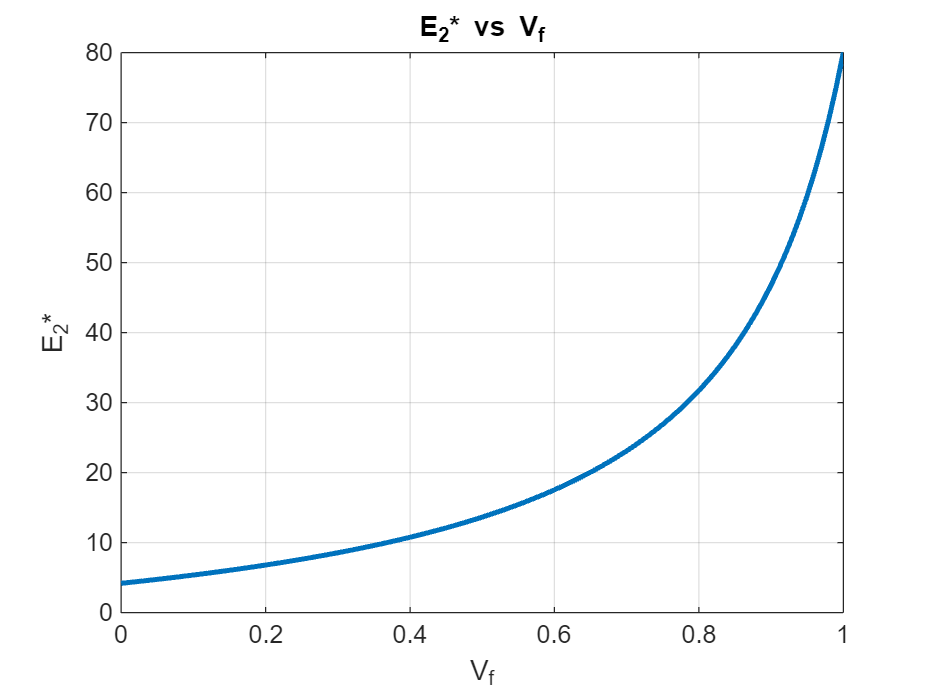


figure;
plot(Vf_val, E2_c_val, 'LineWidth', 2);
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
grid on;

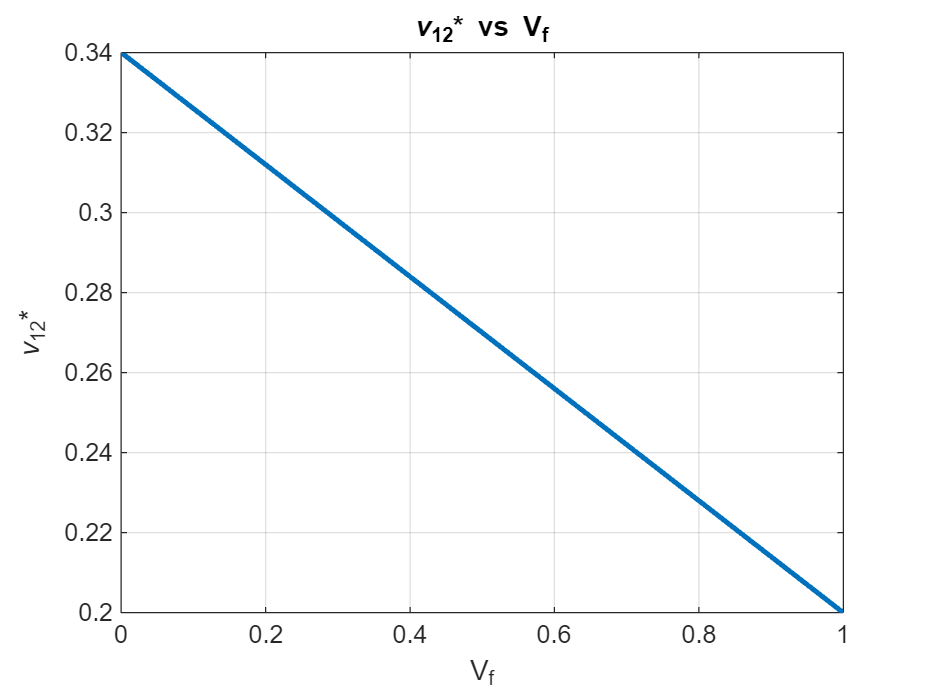


figure;
plot(Vf_val, v12_c_val, 'LineWidth', 2);
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
grid on;

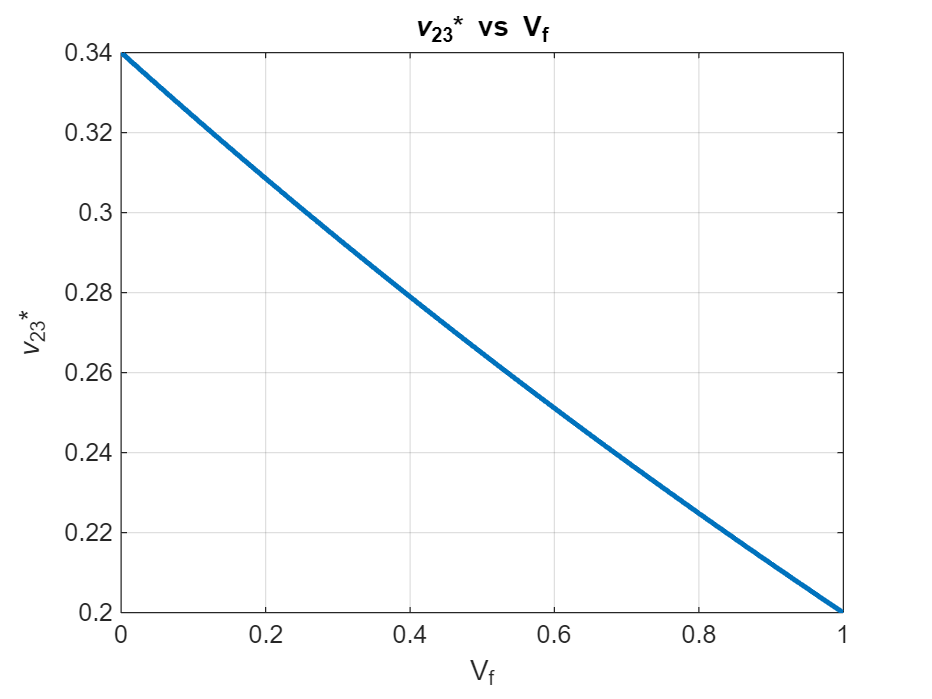


figure;
plot(Vf_val, v23_c_val, 'LineWidth', 2);
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
grid on;

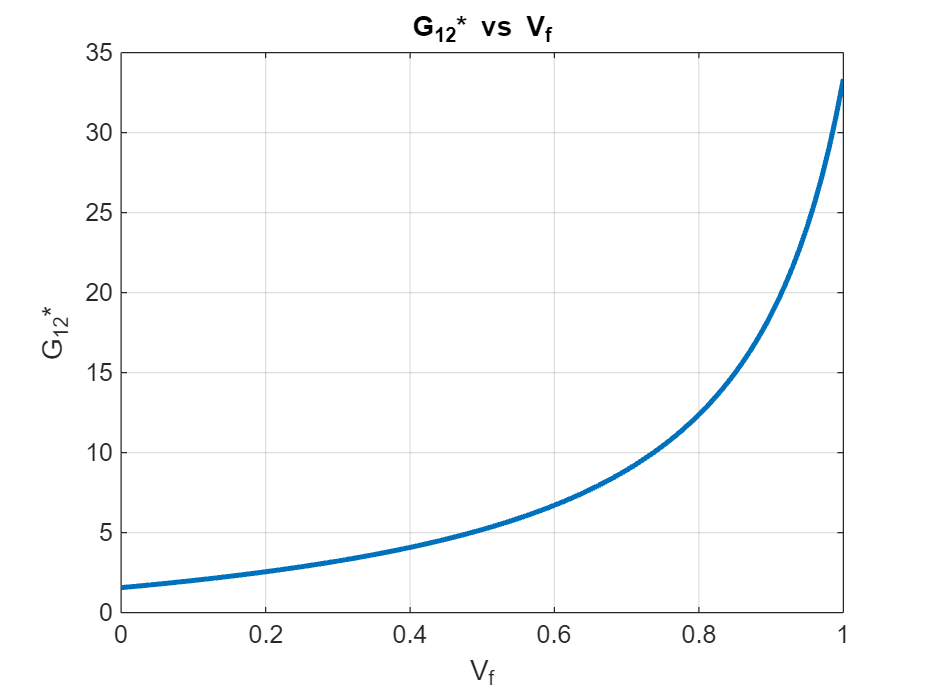


figure;
plot(Vf_val, G12_c_val, 'LineWidth', 2);
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
grid on;

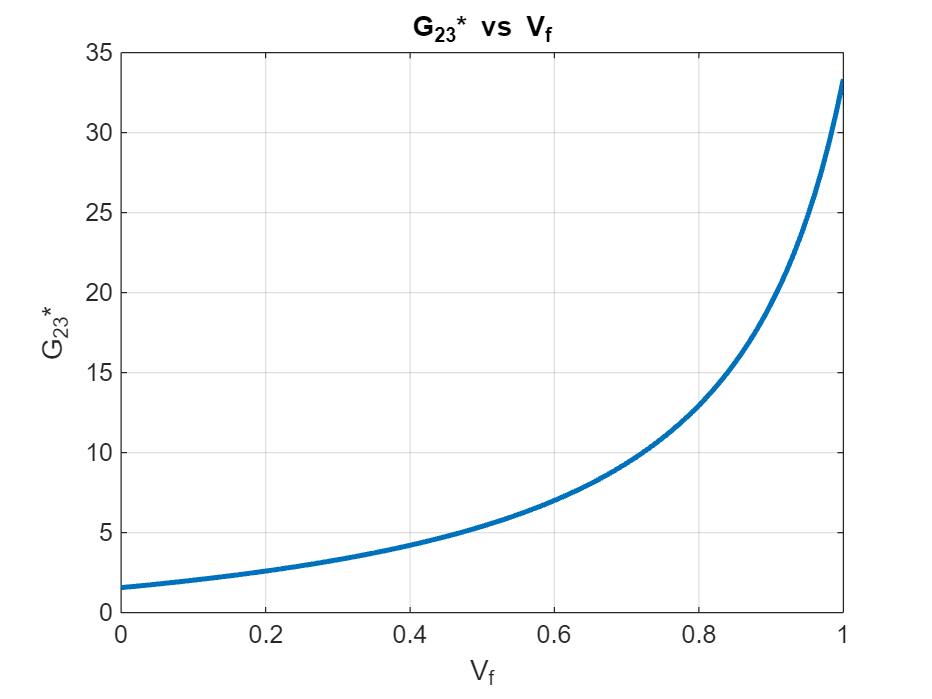


figure;
plot(Vf_val, G23_c_val, 'LineWidth', 2);
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
grid on;